clear all;
AD2close()

library/device seems already closed.


hdwf = AD2Init();

Set variable hfile: C:\Program Files (x86)\Digilent\WaveFormsSDK\inc\dwf.h


Check if dwf library is loaded: islibloaded = 1nVersion: 3.7.20                          
FDwfDeviceOpen returned: 1



% Set initial parameters
frequency = 1e3

frequency = 1000

nSamples = 8000

nSamples = 8000

channel = 0

channel = 0

PressureFactor = 7.60

PressureFactor = 7.6000


% Set status LED
AD2initAnalogOut(hdwf, 1, 0, 5, 0, 7);
AD2StartAnalogOut(hdwf, 1);

% Apply 5v over channels
AD2initAnalogOut(hdwf, 0, 0, 5, 0, 7);
AD2StartAnalogOut(hdwf, 0);

% Wait one second for pressure sensor readings to stabilise
pause(1)

% Take 5 readings of pressure meter (at 0psi) to calculation offset
AD2initAnalogIn(hdwf, channel, frequency, 5, 1000);
AD2StartAnalogIn(hdwf);

% Find mean of the 5 data points array and set as the offset
OffsetVoltage = mean(AD2GetAnalogData(hdwf, channel, 1))

OffsetVoltage = 2.7265

pause(1)

% Now turn off status LED
AD2initAnalogOut(hdwf, 1, 0, 0, 0, 7);
AD2StartAnalogOut(hdwf, 1);
AD2initAnalogOut(hdwf, 0, 1, 5, 0, 4);
AD2StartAnalogOut(hdwf, 0);

% Pause between measurement of offset and general measurements
pause(2)

% Set 5 volts along the voltage rails
AD2initAnalogOut(hdwf, 0, 0, 5, 0, 7);

% Start measurement
AD2initAnalogIn(hdwf, channel, frequency, 5, nSamples);
AD2StartAnalogIn(hdwf);

% Get the data from the AD2 for the input
data = AD2GetAnalogData(hdwf, channel, nSamples);

% Apply the offset, pressure factor and convert it to kPa (by multiplying
% by 6.895)
procdata = -(((data - OffsetVoltage) * PressureFactor) *  6.895)

procdata =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


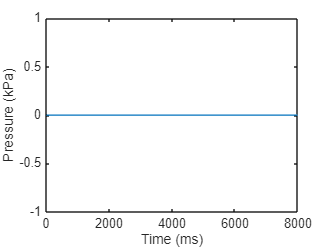


% Plot the data into the graph
plot(procdata);
xlabel('Time (ms)')
ylabel('Pressure (kPa)')


% Display some further statistics of the data measured
disp 'The mean pressure (kPa) measured is'

The mean pressure (kPa) measured is


mean(procdata)

ans = 0


disp 'The maximum pressure (kPa) measured is'

The maximum pressure (kPa) measured is


max(procdata)

ans = 0


disp 'The minimum pressure (kPa) measured is'

The minimum pressure (kPa) measured is


min(procdata)

ans = 0


% Reset the status LEDs
AD2initAnalogOut(hdwf, 0, 0, 0, 0, 7);
AD2initAnalogOut(hdwf, 1, 0.5, 5, 0, 4);
AD2StartAnalogOut(hdwf, 1);

AD2close();

Device closed!
